# **Processat linial d'imatges I**

## Soroll en una imatge

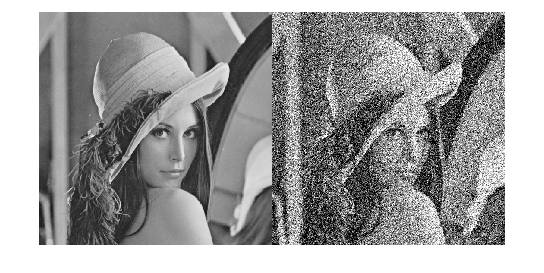

I = imread('lena_gray_512.tif');
% soroll aditiu
J = imnoise(I, 'gaussian', 0, 0.06);
montage({I, J});

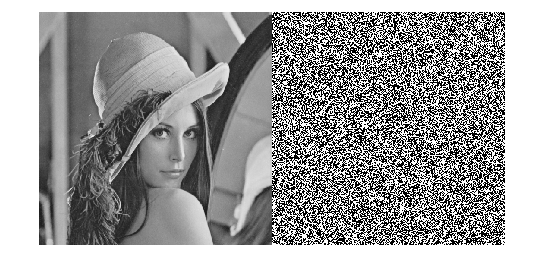

% mostar soroll afegit
R = double(I) - double(J);
montage({I, R});

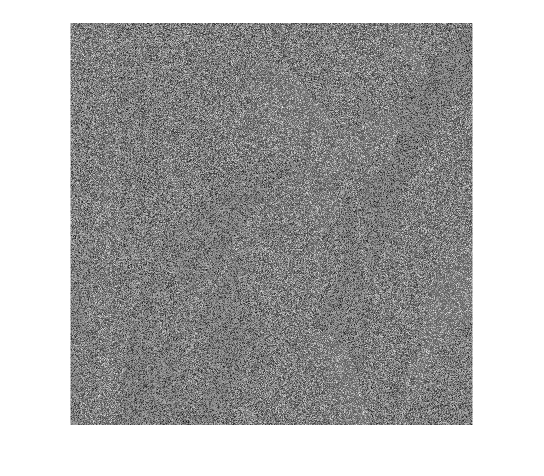

imshow(R, [])

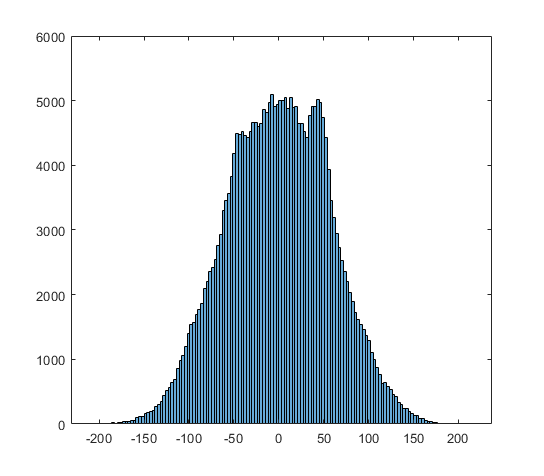

histogram(R)

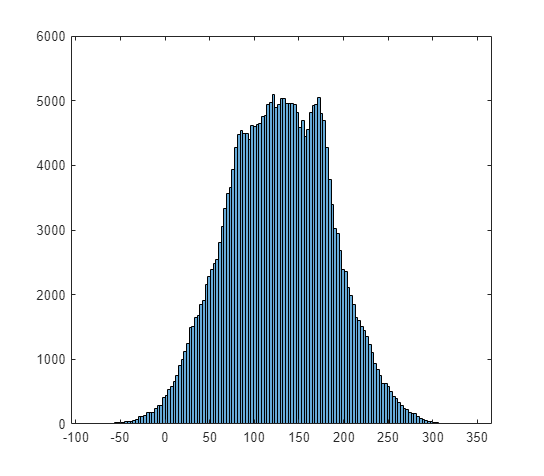

histogram(R+128)

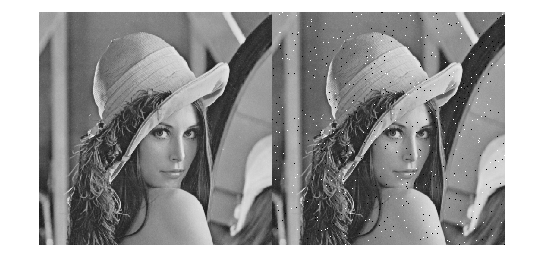

% mostrar soroll salt & pepper
J = imnoise(I, 'salt & pepper', 0.01);
montage({I, J})

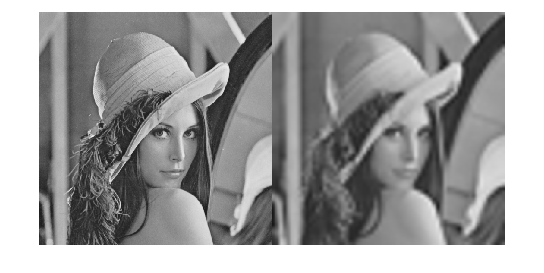

% soroll per reducció d'una imatge
J = imresize(I, [64 64]);
J = imresize(J, [512 512]);
montage({I, J})

## Processat de la imatge

### Augmentar iluminació

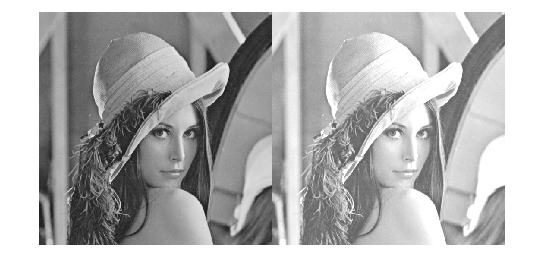

I = imread('lena_gray_512.tif');
HI = imhist(I);
% augmentar la iluminació afegint una constant, no augmenta el contrast
J = I + 64;
HJ = imhist(J);
montage({I, J});

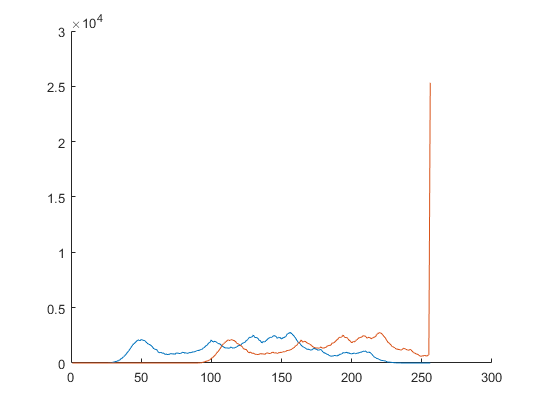

figure;
hold on
plot(HI);
plot(HJ);

### Millorar saturació i contrast d'una imatge (funció pròpia)

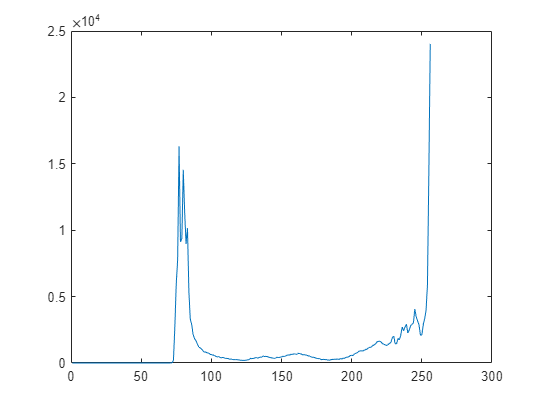

close all
I = rgb2gray(imread('bad_contrast.jpg'));
HI = imhist(I);
plot(HI);

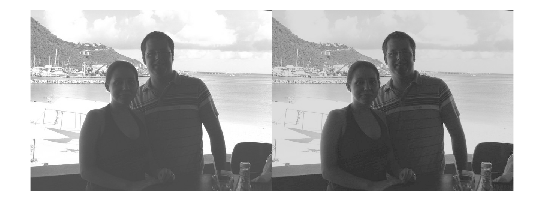

J = arrayfun(@myFunction, double(I));
montage({I, J})

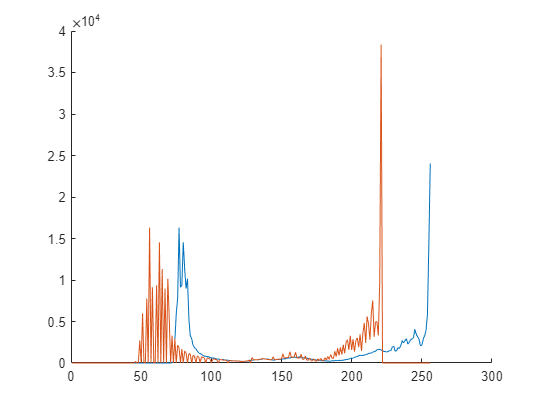

figure;
HJ = imhist(J);
hold on
plot(HI);
plot(HJ);

### Millorar saturació i contrast d'una imatge (funció de MATLAB)

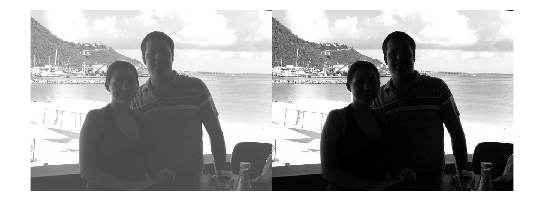

I = rgb2gray(imread('bad_contrast.jpg'));
J = imadjust(I);
montage({I, J})

### Equalització d'una imatge

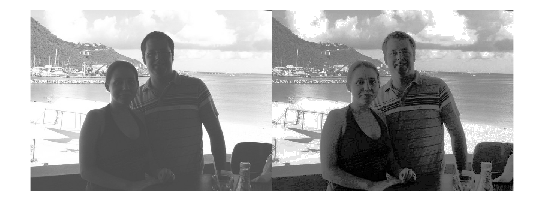

I = rgb2gray(imread('bad_contrast.jpg'));
J = histeq(I);
montage({I, J})

### Transformació d'una imatge

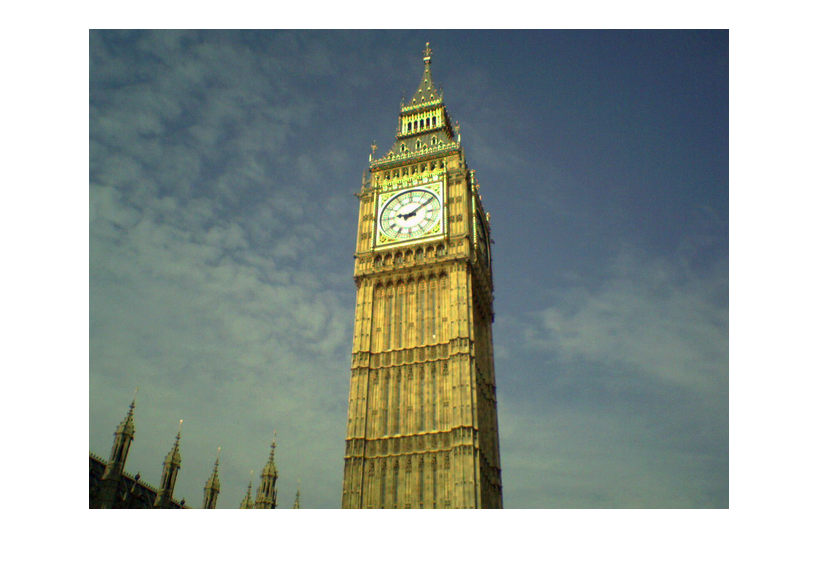

Error using getpts
Interruption during mouse point selection.

I = imread('bigben.png');
imshow(I);
[x,y] = getpts;
[i,j] = getpts;

tform = fitgeotrans([x, y], [i,j], 'projective');
J = imwarp(I, tform, "OutputView", imref2d(size(I)));
montage({I, J});